%%%%%%%%%%%%%%%%%%%%%%
%%% specific analysis of warehouse and shutdowns for Covington
%%% created 1/5/2023
%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%
%%%import data
%%%%%%%%%%%%%%%%%%%%%%

%% find current working folder
fp = fileparts(matlab.desktop.editor.getActiveFilename);
cd(fp) %% change to code folder
cd ../../Data/Processed/EtO/'Data Conversions' %change to data folder

%%canister data, including data with all flags
%SDK
ARSDK = readtimetable("AR SDK.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ARSDKnoLK = readtimetable("AR SDK.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ARSDKnoHg = readtimetable("AR SDK.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");
ARSDKATEC = readtimetable("AR SDK.xlsx", "Sheet", "ATEC", "VariableNamingRule", "preserve");
ARSDKATECnoLK = readtimetable("AR SDK.xlsx", "Sheet", "ATEC no LK", "VariableNamingRule", "preserve");
ARSDKATECnoHg = readtimetable("AR SDK.xlsx", "Sheet", "ATEC no 0 Hg", "VariableNamingRule", "preserve");
ARSDKEnt = readtimetable("AR SDK.xlsx", "Sheet", "Ent", "VariableNamingRule", "preserve");
ARSDKEntnoLK = readtimetable("AR SDK.xlsx", "Sheet", "Ent no LK", "VariableNamingRule", "preserve");
ARSDKEntnoHg = readtimetable("AR SDK.xlsx", "Sheet", "Ent no 0 Hg", "VariableNamingRule", "preserve");

%COV
ARCOV = readtimetable("AR COV.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ARCOVnoLK = readtimetable("AR COV.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ARCOVnoHg = readtimetable("AR COV.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");

%%receptors
cd ..
points = readtable("mapPoints.xlsx", "sheet", ...
    "From Matlab, warehouse center"); %grab receptor with COV warehouse as center

%%met data, but only met data needed
cd ../Met
rawMetSDK = readtimetable("Met_SDK.xlsx"); %SDK data 8/19-8/22
rawMetCOV = readtimetable("WRF wind data.xlsx", "Sheet", "COV"); %COV 5/19-7/22

cd ../..

%%%%%%%%%%%%%%%%%%%%%%
%%% separation of upwind/downwind AR
%%%%%%%%%%%%%%%%%%%%%%

%%INPUTS
dataSDK = ARSDKEnt(:, ["Ent_ERG", "Ent_ERG_2"]); %passive SDK at ERG ONLY
dataCOV = ARCOV; %COV
tol = 50; %minimum tolerance for binning
degUpwind = 90; %upwind degree tolerance
degDownwind = 90; %downwind degree tolerance
WDRCOV = rawMetCOV(:, "WDR"); %wind COV

%%pre-format for separation function
%COV; KEY MODIFICATION: C1 ALWAYS DOWNWIND bc at fenceline
temp = table2array(points(19:26, [5, 6])); %C2, C3, C4, C5, C7, C8, C9
%match column structure of COV eto table
receptorsCOV = [temp(1, :)', temp(2, :)', temp(2, :)', ...
    temp(3, :)', temp(3, :)', temp(4, :)', temp(4, :)', temp(5, :)', temp(5, :)',...
    temp(6, :)', temp(7, :)', temp(8, :)'];
receptorsCOV = array2table(receptorsCOV); %turn into table
%rename to match etoCOV (except for C1)
varNames = ARCOV.Properties.VariableNames;
receptorsCOV = renamevars(receptorsCOV, receptorsCOV.Properties.VariableNames, ...
    varNames);
degFromNCOV = table2array(receptorsCOV(2, :));

%%separation function
[upwindCOV, downwindCOV, unbinnedCOV, percUpwindWDRCOV, percDownwindWDRCOV, statsCOV] = ...
    upwindDownwind(degFromNCOV, degUpwind, degDownwind, WDRCOV, tol, dataCOV);

%%grab inds or days with coupled observations
%all data
outTTCOV = avSameTime(dataSDK, dataCOV); %[SDKavg, SDKstd, COVavg, COVstd]

%upwind
outUpwindTTCOV = avSameTime(dataSDK, upwindCOV); %[SDKavg, SDKstd, COVavg, COVstd]

%downwind
outDownwindTTCOV = avSameTime(dataSDK, downwindCOV); %[SDKavg, SDKstd, COVavg, COVstd]

%%subtraction of each individual near-source site by SDK, separated also by upwind, downwind, and all

%COV
inds = ismember(dataCOV.time, outTTCOV.time); %times SDK and COV match
temp = timetable2array(dataCOV(inds, :)); %grab all COV data
temp = temp - repmat(outTTCOV.avg1, 1, size(temp, 2));
diffCOV = array2timetable(temp, "RowTimes", outTTCOV.time, ...
    "VariableNames", dataCOV.Properties.VariableNames); %COV

inds = ismember(upwindCOV.time, outUpwindTTCOV.time); %times SDK and upwind COV match
temp = timetable2array(upwindCOV(inds, :)); %grab all upwind COV data
temp = temp - repmat(outUpwindTTCOV.avg1, 1, size(temp, 2));
diffUpwindCOV = array2timetable(temp, "RowTimes", outUpwindTTCOV.time, ...
    "VariableNames", dataCOV.Properties.VariableNames); %COV, upwind

inds = ismember(downwindCOV.time, outDownwindTTCOV.time); %times SDK and downwind COV match
temp = timetable2array(downwindCOV(inds, :)); %grab all downwind COV data
temp = temp - repmat(outDownwindTTCOV.avg1, 1, size(temp, 2));
diffDownwindCOV = array2timetable(temp, "RowTimes", outDownwindTTCOV.time, ...
    "VariableNames", dataCOV.Properties.VariableNames); %COV, downwind


%%OUTPUTS
upwindCOV; downwindCOV; unbinnedCOV; %separated data for COV
diffCOV; diffUpwindCOV; diffDownwindCOV; %difference data for COV
outTTCOV; outUpwindTTCOV; outDownwindTTCOV; %averaged data for pairwise observations

%% shutdown

shutdownCOV = datetime([2019, 2019, 2020, 2020], ...
    [10, 11, 2, 3], ...
    [30, 8, 22, 2]); %shutdowns between Oct 30 and Nov 8, 2019 and Feb 22 and Mar 2, 2020
indsShutdown = isbetween(diffCOV.Properties.RowTimes, shutdownCOV(1), shutdownCOV(2)); %first period
indsShutdown = indsShutdown | ...
    isbetween(diffCOV.Properties.RowTimes, shutdownCOV(3), shutdownCOV(4)); %second period

%%%%%%%%%%%%%%%%%%%%%%
%%% evaluate different controls date
%%%%%%%%%%%%%%%%%%%%%%

colorUpwind = [73, 191, 162]/255;
colorDownwind = [226, 84, 175]/255;
controlsCOV = datetime(2020, 12, 31);

%%% COV
fig3 = figure('Position', get(0, 'Screensize')); %for saving the figure
tiledlayout(1, 3)

%%1. time series, COV
xlims = datetime([2019, 2022], [7, 1], 1);
xtickss = xlims(1):calmonths(6):xlims(2);
ax = nexttile([1, 2]);
hold on
grid on
box on

%upwind COV
diffDataUpwindMonthCOV = binByMonth(diffUpwindCOV); %upwind COV, bin by month
times = datenum(diffDataUpwindMonthCOV.Properties.RowTimes); %grab date nums
[hl3, hp] = boundedline(times, diffDataUpwindMonthCOV.avgs, diffDataUpwindMonthCOV.stds, ...
    'o-', 'nan', 'gap', 'alpha', 'transparency', 0.17, 'color', colorUpwind);
hl3.MarkerSize = 8; %change line aspects
hl3.MarkerFaceColor = colorUpwind;
hl3.LineWidth = 3;

%downwind COV
diffDataDownwindMonthCOV = binByMonth(diffDownwindCOV); %downwind COV, bin by month
times = datenum(diffDataDownwindMonthCOV.Properties.RowTimes); %grab date nums
[hl4, hp] = boundedline(times, diffDataDownwindMonthCOV.avgs, diffDataDownwindMonthCOV.stds, ...
    '^-', 'nan', 'gap', 'alpha', 'transparency', 0.17, 'color', colorDownwind);
hl4.MarkerSize = 8; %change line aspects
hl4.MarkerFaceColor = colorDownwind;
hl4.LineWidth = 3;

%controls lines
xline(datenum(controlsCOV), '--', "linewidth", 2, ...
    "color", "k") %COV
yline(0, '-', "color", [0.5, 0.5, 0.5], "linewidth", 1.3) %comparison against 0 enhancement

% patch for shutdown
% first period
x = datenum(datetime(2019,...
    [10, 11, 11, 10], [30, 8, 8, 30])); %shutdown timeline
y = [-1, -1, 1, 1];
p = patch(x, y, 'red');
p.FaceColor = patchColor; % gray
p.EdgeColor = 'none';
p.FaceAlpha = 0.2; % mostly transparent
% second period
x = datenum(datetime(2020,...
    [2, 3, 3, 2], [22, 2, 2, 22])); %shutdown timeline
y = [-1, -1, 1, 1];
p = patch(x, y, 'red');
p.FaceColor = patchColor; % gray
p.EdgeColor = 'none';
p.FaceAlpha = 0.2; % mostly transparent

%move lines to top
uistack(hl3, 'top')
uistack(hl4, 'top')

%%lims and ticks
xlim(datenum(xlims))
xticks(datenum(xtickss))
ax.XTickLabel = datestr(xtickss, "mmm yyyy");
ylim([-0.0104, 0.0104])
yticks(-0.01:0.005:0.01)
ax.YTickLabel = ["-0.010", "-0.005", "0", "0.005", "0.010"];

%%labels
pbaspect([3, 1, 1])
ax.FontSize = 20;
xlabel("Local Time (EST)")
ylabel("AR Enhancement")
legend("", "", "", "", "", "", ...
    strcat("upwind, n=", num2str(length(unravelTT(diffUpwindCOV)))), ...
    strcat("downwind, n=", num2str(length(unravelTT(diffDownwindCOV)))))

hold off



%%2. histograms, COV
ax = nexttile;
hold on
grid on
box on

% binWidths = 0.0025;
binWidths = 0.0015;

%%all data as histograms
indsBefore = diffCOV.Properties.RowTimes < controlsCOV; %before controls, exclude shutdown
h1 = histogram(unravelTT(diffCOV(indsBefore & ~indsShutdown, :)), "Normalization", "probability");
h1.BinWidth = binWidths;
h1.EdgeColor = "none"; %remove outer outline
h1.FaceAlpha = 0.5;
h1.FaceColor = beforeColor;
median(unravelTT(diffCOV(indsBefore & ~indsShutdown, :)))

ans = 1.5000e-04


indsAfter = diffCOV.Properties.RowTimes >= controlsCOV; %after controls
h2 = histogram(unravelTT(diffCOV(indsAfter, :)), "Normalization", "probability");
h2.BinWidth = binWidths;
h2.EdgeColor = "none"; %remove outer outline
h2.FaceAlpha = 0.5;
h2.FaceColor = afterColor;
median(unravelTT(diffCOV(indsAfter, :)))

ans = 5.0000e-05

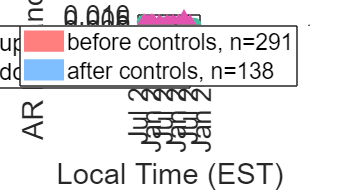


%%line at SDK uncertainties to signify comparison 
xline(0.0012, "--", "color", [0.3, 0.3, 0.3], "LineWidth", 1.3)
xline(-0.0012, "--", "color", [0.3, 0.3, 0.3], "LineWidth", 1.3)

%%lims
xlim([-0.0209, 0.0259])
xticks(-0.020:0.01:0.020)
ylim([0, 0.8])
% yticks(0:15:60)

%%labels
pbaspect([1.3, 1, 1])
ax.FontSize = 20;
xlabel("AR Enhancement")
ylabel("Normalized Observation Counts")

legend(strcat("before controls, n=", num2str(length(unravelTT(diffCOV(indsBefore & ~indsShutdown, :))))), ...
    strcat("after controls, n=", num2str(length(unravelTT(diffCOV(indsAfter, :))))), ...
    "location", "northeast", "Fontsize", 17)
% legend boxoff

hold off

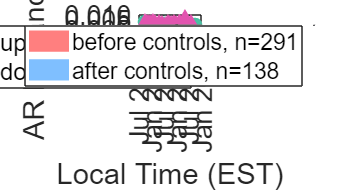

%%% export figures
cd ..\Figures
a = annotation('rectangle',[0 0 1 1],'Color','w'); %add padding
fn = "Sup COV Warehouse.png";
exportgraphics(fig3, fn)
delete(a) %make plot interactive again


cd ..\Data

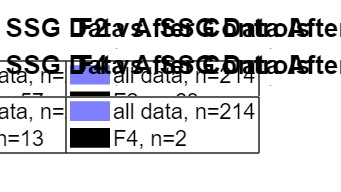

%%%%%%%%%%%%%%%%%%%%%%
%%% Supplemental Figures
%%%%%%%%%%%%%%%%%%%%%%

%%%plot F1, F2, F3, and F4 separately
% colors = [1, 0, 0;
%     0, 0, 1;
%     0.071, 0.74, 0.74;
%     0.769, 0.080, 0.557];
indsReceptor = {[1, 2], [3, 4],  5, [6, 7]};
names = ["F1", "F2", "F3", "F4"];
medianF = [];

fig = figure('Position', get(0, 'Screensize')); %for saving the figure
tiledlayout(2, 2)
for i = 1:length(indsReceptor)
    inds = diffSSG.Properties.RowTimes < controlsSSG; %before or after controls
%     inds = diffSSG.Properties.RowTimes >= datetime(1990, 1, 1); %for normal circumstances
    nReceptor = length(unravelTT(diffSSG(inds, indsReceptor{i})));

    ax = nexttile;
    hold on
    grid on
    box on

    binWidths = 0.002;

    %%all data
    h = histogram(unravelTT(diffSSG(inds, :)), "Normalization", "probability");
    h.BinWidth = binWidths;
    h.EdgeColor = "none"; %remove outer outline
    h.FaceAlpha = 0.5;
    h.FaceColor = 'b';

    %%this particular receptor's data
    h1 = histogram(unravelTT(diffSSG(inds, indsReceptor{i})));
    h1.BinWidth = binWidths;
    h1.EdgeColor = "none"; %remove outer outline
    h1.FaceAlpha = 1;
    h1.FaceColor = 'k';
    h1.BinCounts = h1.BinCounts/length(unravelTT(diffSSG(inds, :))); %normalize to other plot
    medianF(i) = median(unravelTT(diffSSG(inds, indsReceptor{i})));
    
    %%line at 0 to signify comparison against 0
    xline(0, "--", "color", [0.3, 0.3, 0.3], "LineWidth", 1.3)

    %%lims
    xlim([-0.021, 0.031])
    xticks(-0.02:0.01:0.03)
    ylim([0, 0.45])
    yticks(0:0.15:0.45)

    %%labels
    pbaspect([1.3, 1, 1])
    ax.FontSize = 18;
    xlabel("AR Enhancement")
    ylabel("Normalized Observation Counts")
    title(strcat(names(i), " vs. SSG Data After Controls"))

    legend("all data, n=214", ...
        strcat(names(i), ", n=", num2str(nReceptor)), ...
        "location", "northeast")
    % legend boxoff

    hold off
end


% %%export the figure
% cd ..\Figures
% a = annotation('rectangle',[0 0 1 1],'Color','w'); %add padding
% fn = "Sup SSG All Sites After Controls.png";
% exportgraphics(fig, fn)
% delete(a) %make plot interactive again
% cd ..\Data

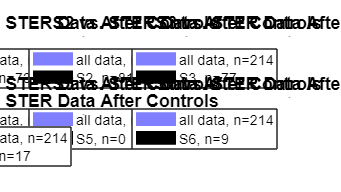

%%%plot S1 to S7 separately
% colors = [1, 0, 0;
%     0, 0, 1;
%     0.071, 0.74, 0.74;
%     0.769, 0.080, 0.557];
indsReceptor = {[1, 2], [3, 4],  [5, 6], [7, 8], 9, 10, 11};
names = ["S1", "S2", "S3", "S4", "S5", "S6", "S7"];
medianS = [];

fig = figure('Position', get(0, 'Screensize')); %for saving the figure
tiledlayout(3, 3)
for i = 1:length(indsReceptor)
    inds = diffSTER.Properties.RowTimes >= controlsSTER; %before or after controls
%     inds = diffSTER.Properties.RowTimes >= datetime(1990, 1, 1); %for normal circumstances
    nReceptor = length(unravelTT(diffSTER(inds, indsReceptor{i})));

    ax = nexttile;
    hold on
    grid on
    box on

    binWidths = 0.002;

    %%all data
    h = histogram(unravelTT(diffSTER(inds, :)), "Normalization", "probability");
    h.BinWidth = binWidths;
    h.EdgeColor = "none"; %remove outer outline
    h.FaceAlpha = 0.5;
    h.FaceColor = 'b';

    %%this particular receptor's data
    h1 = histogram(unravelTT(diffSTER(inds, indsReceptor{i})));
    h1.BinWidth = binWidths;
    h1.EdgeColor = "none"; %remove outer outline
    h1.FaceAlpha = 1;
    h1.FaceColor = 'k';
    h1.BinCounts = h1.BinCounts/length(unravelTT(diffSTER(inds, :))); %normalize to other plot
    medianS(i) = median(unravelTT(diffSTER(inds, indsReceptor{i})));
    
    %%line at 0 to signify comparison against 0
    xline(0, "--", "color", [0.3, 0.3, 0.3], "LineWidth", 1.3)

    %%lims
    xlim([-0.021, 0.031])
    xticks(-0.02:0.01:0.03)
    ylim([0, 0.45])
    yticks(0:0.15:0.45)

    %%labels
    pbaspect([1.3, 1, 1])
    ax.FontSize = 12;
    xlabel("AR Enhancement")
    ylabel("Normalized Observation Counts")
    title(strcat(names(i), " vs. STER Data After Controls"))

    legend("all data, n=214", ...
        strcat(names(i), ", n=", num2str(nReceptor)), ...
        "location", "northeast")
    % legend boxoff

    hold off
end


% %%export the figure
% cd ..\Figures
% a = annotation('rectangle',[0 0 1 1],'Color','w'); %add padding
% fn = "Sup STER All Sites After Controls.png";
% exportgraphics(fig, fn)
% delete(a) %make plot interactive again
% cd ..\Data

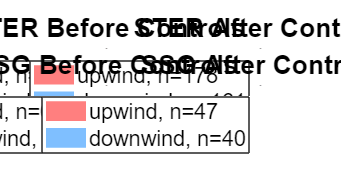

%%%plot upwind/downwind and before/after controls
% colors = [1, 0, 0;
%     0, 0, 1;
%     0.071, 0.74, 0.74;
%     0.769, 0.080, 0.557];
indsReceptor = {[1, 2], [3, 4],  5, [6, 7]};
titles = ["STER Before Controls", "STER After Controls", ...
    "SSG Before Controls", "SSG After Controls"];
toPlot = {diffUpwindSTER, diffDownwindSTER;
    diffUpwindSSG, diffDownwindSSG};
controlsDates = {controlsSTER, controlsSSG};

fig = figure('Position', get(0, 'Screensize')); %for saving the figure
tiledlayout(2, 2)
for i = 1:length(indsReceptor)

    %%get data to plot
    toPlotUpwind = toPlot{ceil(i/2), 1};
    toPlotDownwind = toPlot{ceil(i/2), 2};
    %filter for before or after controls
    if mod(i, 2) == 1 %if odd, before controls
        inds = toPlotUpwind.Properties.RowTimes < controlsDates{ceil(i/2)};
        toPlotUpwind = toPlotUpwind(inds, :);
        inds = toPlotDownwind.Properties.RowTimes < controlsDates{ceil(i/2)};
        toPlotDownwind = toPlotDownwind(inds, :);
    else
        inds = toPlotUpwind.Properties.RowTimes >= controlsDates{ceil(i/2)};
        toPlotUpwind = toPlotUpwind(inds, :);
        inds = toPlotDownwind.Properties.RowTimes >= controlsDates{ceil(i/2)};
        toPlotDownwind = toPlotDownwind(inds, :);
    end
    
    ax = nexttile;
    hold on
    grid on
    box on

    binWidths = 0.002;
    
    %%all data as histograms
    h1 = histogram(unravelTT(toPlotUpwind), "Normalization", "probability");
    h1.BinWidth = binWidths;
    h1.EdgeColor = "none"; %remove outer outline
    h1.FaceAlpha = 0.5;
    h1.FaceColor = beforeColor;

    inds = diffSSG.Properties.RowTimes >= controlsSSG; %after controls
    h = histogram(unravelTT(toPlotDownwind), "Normalization", "probability");
    h.BinWidth = binWidths;
    h.EdgeColor = "none"; %remove outer outline
    h.FaceAlpha = 0.5;
    h.FaceColor = afterColor;

    %%line at 0 to signify comparison against 0
    xline(0, "--", "color", [0.3, 0.3, 0.3], "LineWidth", 1.3)

    %%lims
    xlim([-0.021, 0.031])
    xticks(-0.02:0.01:0.03)
%     ylim([0, 0.45])
%     yticks(0:0.15:0.45)

    %%labels
    pbaspect([1.3, 1, 1])
    ax.FontSize = 18;
    xlabel("AR Enhancement")
    ylabel("Normalized Observation Counts")
    title(titles(i))

    legend(strcat("upwind, n=", num2str(length(unravelTT(toPlotUpwind)))), ...
        strcat("downwind, n=", num2str(length(unravelTT(toPlotDownwind)))), ...
        "location", "northeast")
    % legend boxoff

    hold off
end


% %%export the figure
% cd ..\Figures
% a = annotation('rectangle',[0 0 1 1],'Color','w'); %add padding
% fn = "Sup STER and SSG Upwind-Downwind.png";
% exportgraphics(fig, fn)
% delete(a) %make plot interactive again
% cd ..\Data